clear
clc
clf
% dados da curva
sp_u = [20 25 30 35];
sp_h3 = [18.31 28.24 38.16 50.79]*1e-2;
sp_h4 = [25.71 38.5 50.78 65.52]*1e-2;
d_h = sp_h4-sp_h3;
%
syms dh u
qi = piecewise(u<20,0,u>=20,(16.4*u + 357.3)*1e-6)

$$qi = \left\{ \begin{array}{cl} 0 & \text{ if }u<20\\ \frac{41\,u}{2500000}+\frac{3573}{10000000} & \text{ if }20\leq u \end{array}\right.$$

sp_qi = vpa(subs(qi,u,sp_u),3)

$$sp\_qi = \left(\begin{array}{cccc} 6.85\,10^{-4} & 7.67\,10^{-4} & 8.49\,10^{-4} & 9.31\,10^{-4} \end{array}\right)$$

plot(d_h,sp_qi,'*b','LineWidth',1)
hold on
grid
q12 = fit(d_h',sp_qi','poly1')

q12 =      Linear model Poly1:
     q12(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    0.003351  (0.002641, 0.004061)
       p2 =   0.0004312  (0.000349, 0.0005134)

plot(d_h,vpa(q12(d_h)',3),'-r','LineWidth',2)
% Desvio do erro
erro = vpa(max(vpa(q12(d_h)',3) - sp_qi),3)

$$erro = 7.74\,10^{-6}$$

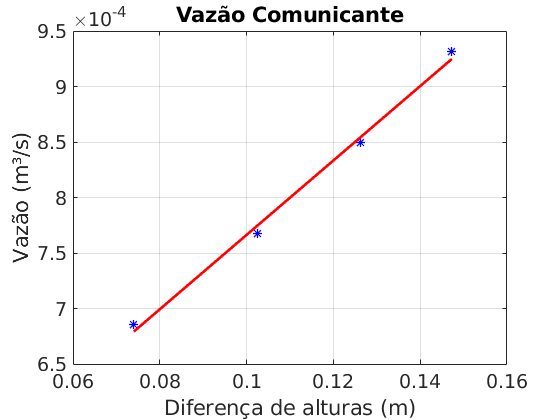

title('Vazão Comunicante')
ylabel('Vazão (m³/s)')
xlabel('Diferença de alturas (m)')
opt = gca;
opt.FontSize = 14;

figure
plot(sqrt(d_h),sp_qi,'*')
s_q12 = fit(sqrt(d_h'),sp_qi','poly1')

s_q12 =      Linear model Poly1:
     s_q12(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    0.002183  (0.001382, 0.002984)
       p2 =   8.169e-05  (-0.0001871, 0.0003505)

hold on
plot(sqrt(d_h),vpa(s_q12(sqrt(d_h))',3)')
% Desvio do erro 
s_erro = vpa(max(vpa(s_q12(sqrt(d_h))',3) - sp_qi),3)

$$s\_erro = 1.36\,10^{-5}$$

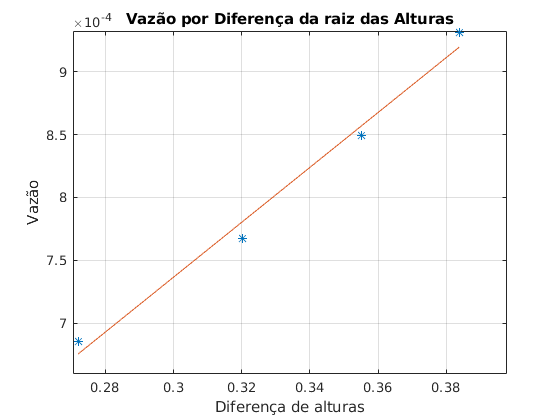

title('Vazão por Diferença da raiz das Alturas')
ylabel('Vazão')
xlabel('Diferença de alturas')
grid

figure
plot(sp_h3,sp_qi,'*')
grid
qout = fit(sp_h3',sp_qi','poly1')

qout =      Linear model Poly1:
     qout(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0007609  (0.0006181, 0.0009037)
       p2 =   0.0005505  (0.0004992, 0.0006019)

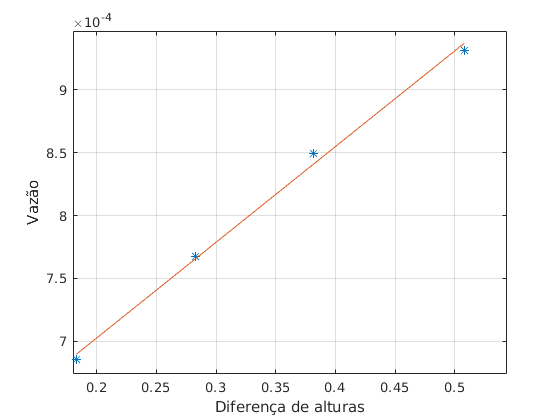

hold on
plot(sp_h3,vpa(qout(sp_h3)',3))
ylabel('Vazão')
xlabel('Diferença de alturas')

% Desvio do erro 
erro_qout = vpa(max(vpa(qout(sp_h3)',3) - sp_qi),3)

$$erro\_qout = 5.7\,10^{-6}$$

figure
grid
plot(sqrt(sp_h3),sp_qi,'*b','LineWidth',1)
s_qout = fit(sqrt(sp_h3)',sp_qi','poly1')

s_qout =      Linear model Poly1:
     s_qout(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0008707  (0.0007802, 0.0009613)
       p2 =   0.0003099  (0.0002572, 0.0003626)

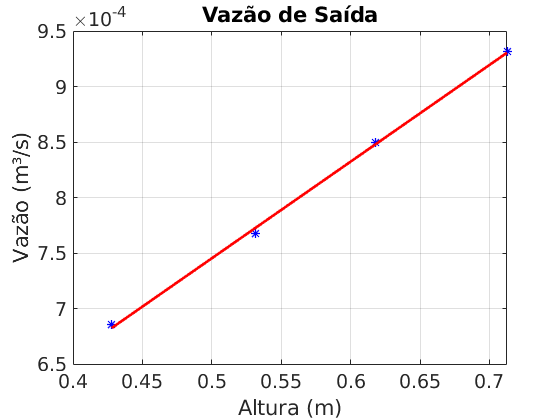

hold on
plot(sqrt(sp_h3),vpa(s_qout(sqrt(sp_h3)'),3),'-r','LineWidth',2)
title('Vazão de Saída')
ylabel('Vazão (m³/s)')
xlabel('Altura (m)')
opt = gca;
opt.FontSize = 14;
grid

% Desvio do erro 
s_erro_qout = vpa(max(vpa(s_qout(sqrt(sp_h3))',3) - sp_qi),3)

$$s\_erro\_qout = 5.28\,10^{-6}$$